clear;
syms t  dx1 dx2 dx3 z1(t) z2(t) z3(t) x1(t) x2(t) x3(t) v u;
load_system('svlvspr2_schema_SVLVS.slx');
Tsim = 15;
pidW = 10;

dz1(t) = diff(z1(t), t);
dz2(t) = diff(z2(t), t);
dz3(t) = diff(z3(t), t);

sysZE{1} = dz1 == z2;
sysZE{2} = dz2 == z3;
sysZE{3} = dz3 == u - cos(z1)*(z2+z3);

zE{1} = z1 == -x2;
zE{2} = z2 == x1 + x2;
zE{3} = z3 == sin(x2) - x3;

lambda1 = -1;
lambda2 = -1;
lambda3 = -1;

% sysZE{1} = dz1 == -z1 + z2;
% sysZE{2} = dz2 == u - z2 + sin(z1)-2*z1+cos(z1)*(z2-z1);
% zE{1} = z1 == x1;
% zE{2} = z2 == x2+sin(x1);

sysZEq = [];
zEq = [];
for i = 1 : size(sysZE,2)
    sysZEq = [sysZEq;sysZE{i}];
    zEq = [zEq;zE{i}];
end

sysZEq

$$sysZEq(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}z_{1}\left(t\right)=z_{2}\left(t\right)\\ \frac{\partial }{\partial t}z_{2}\left(t\right)=z_{3}\left(t\right)\\ \frac{\partial }{\partial t}z_{3}\left(t\right)=u-\cos\left(z_{1}\left(t\right)\right)\,\left(z_{2}\left(t\right)+z_{3}\left(t\right)\right) \end{array}\right)$$

zEq

$$zEq(t) = \left(\begin{array}{c} z_{1}\left(t\right)=-x_{2}\left(t\right)\\ z_{2}\left(t\right)=x_{1}\left(t\right)+x_{2}\left(t\right)\\ z_{3}\left(t\right)=\sin\left(x_{2}\left(t\right)\right)-x_{3}\left(t\right) \end{array}\right)$$

## Vypocet povodneho systemu

dzEq = diff(zEq, t)

$$dzEq(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}z_{1}\left(t\right)=-\frac{\partial }{\partial t}x_{2}\left(t\right)\\ \frac{\partial }{\partial t}z_{2}\left(t\right)=\frac{\partial }{\partial t}x_{1}\left(t\right)+\frac{\partial }{\partial t}x_{2}\left(t\right)\\ \frac{\partial }{\partial t}z_{3}\left(t\right)=\cos\left(x_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}x_{2}\left(t\right)-\frac{\partial }{\partial t}x_{3}\left(t\right) \end{array}\right)$$

sEq1 = subs(dzEq, lhs(sysZEq), rhs(sysZEq))

$$sEq1(t) = \left(\begin{array}{c} z_{2}\left(t\right)=-\frac{\partial }{\partial t}x_{2}\left(t\right)\\ z_{3}\left(t\right)=\frac{\partial }{\partial t}x_{1}\left(t\right)+\frac{\partial }{\partial t}x_{2}\left(t\right)\\ u-\cos\left(z_{1}\left(t\right)\right)\,\left(z_{2}\left(t\right)+z_{3}\left(t\right)\right)=\cos\left(x_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}x_{2}\left(t\right)-\frac{\partial }{\partial t}x_{3}\left(t\right) \end{array}\right)$$

sEq6 = subs(sEq1, lhs(zEq), rhs(zEq))

$$sEq6(t) = \left(\begin{array}{c} x_{1}\left(t\right)+x_{2}\left(t\right)=-\frac{\partial }{\partial t}x_{2}\left(t\right)\\ \sin\left(x_{2}\left(t\right)\right)-x_{3}\left(t\right)=\frac{\partial }{\partial t}x_{1}\left(t\right)+\frac{\partial }{\partial t}x_{2}\left(t\right)\\ u-\cos\left(x_{2}\left(t\right)\right)\,\left(\sin\left(x_{2}\left(t\right)\right)+x_{1}\left(t\right)+x_{2}\left(t\right)-x_{3}\left(t\right)\right)=\cos\left(x_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}x_{2}\left(t\right)-\frac{\partial }{\partial t}x_{3}\left(t\right) \end{array}\right)$$

sEq7 = subs(sEq6, diff(x1(t), t), dx1);
sEq8 = subs(sEq7, diff(x2(t), t), dx2);
sEq9 = subs(sEq8, diff(x3(t), t), dx3);
[eq{1} eq{2} eq{3}] = solve(sEq9, [dx1 dx2 dx3]);

## Vytvorenie riadenia

uEqq = u - rhs(sysZE{end})

$$uEqq(t) = \cos\left(z_{1}\left(t\right)\right)\,\left(z_{2}\left(t\right)+z_{3}\left(t\right)\right)$$

eq{4} = subs(uEqq, lhs(zEq), rhs(zEq));

syms k1 k2 k3 x y z;
ssEq = [];

for i = 1:size(sysZE,2)-1
   ssEq = [ssEq;rhs(sysZE{i})==0];
end

if size(sysZE,2) == 3
    ssEq = [ssEq;-z1-z2-z3==0];
else
    ssEq = [ssEq;-z1-z2==0];
end


ssEq = subs(ssEq, [z1(t) z2(t) z3(t)], [x y z]);

A = equationsToMatrix(ssEq);

A(end,1) = -k1;
A(end,2) = -k2;

if size(sysZE,2) == 3
    A(end,3) = -k3;
end

e = eig(A)

$$e = \begin{array}{l} \left(\begin{array}{c} \sigma_{2}-\frac{k_{3}}{3}-\frac{\sigma_{3}}{\sigma_{2}}\\ \frac{\sigma_{3}}{2\,\sigma_{2}}-\frac{\sigma_{2}}{2}-\frac{k_{3}}{3}-\sigma_{1}\\ \frac{\sigma_{3}}{2\,\sigma_{2}}-\frac{\sigma_{2}}{2}-\frac{k_{3}}{3}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\sigma_{2}+\frac{\sigma_{3}}{\sigma_{2}}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\frac{k_{2}\,k_{3}}{6}-\frac{k_{1}}{2}+\sqrt{{\sigma_{3}}^{3}+{\left(\frac{{k_{3}}^{3}}{27}-\frac{k_{2}\,k_{3}}{6}+\frac{k_{1}}{2}\right)}^{2}}-\frac{{k_{3}}^{3}}{27}\right)}^{1/3}\\ \sigma_{3}=\frac{k_{2}}{3}-\frac{{k_{3}}^{2}}{9} \end{array}$$


if size(sysZE,2) == 3
    ssEQ = [e(1) == lambda1; e(2) == lambda2; e(3) == lambda3];
else
    ssEQ = [e(1) == lambda1; e(2) == lambda2];
end

k(1) = 1;
ssEQ = subs(ssEQ, k1, k(1));

S = solve(ssEQ);
k(2) = S.k2(end);
k(3) = S.k3(end);

k = double(k)

k =      1     3     3


K = 1 / k(1);

if size(sysZE,2) == 3
    A = subs(A, [k1 k2 k3], [k(1) k(2) k(3)])
else
    A = subs(A, [k1 k2], [k(1) k(2)])
end

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -1 & -3 & -3 \end{array}\right)$$


eig(A)

$$ans = \left(\begin{array}{c} -1\\ -1\\ -1 \end{array}\right)$$


eq{6} = rhs(zE{1});
eq{7} = rhs(zE{2});

if size(sysZE,2) == 3
    eq{8} = rhs(zE{3});
else
    eq{8} = 0;
end

## Simulacia

syms u(t)

for i = 1 : 3
    eq{i} = subs(eq{i}, [u x1 x2 x3], [u(1) u(2) u(3) u(4)]);
end

eq{4} = subs(eq{4}, [x1 x2 x3], [u(1) u(2) u(3)]);

for i = 6 : 8
    eq{i} = subs(eq{i}, [x1 x2 x3], [u(1) u(2) u(3)]);
end

set_param('svlvspr2_schema_SVLVS/System/Fcn','Expression',string(eq{1}));
set_param('svlvspr2_schema_SVLVS/System/Fcn1','Expression',string(eq{2}));
set_param('svlvspr2_schema_SVLVS/System/Fcn2','Expression',string(eq{3}));

set_param('svlvspr2_schema_SVLVS/Subsystem1/Fcn1','Expression',string(eq{4}));

set_param('svlvspr2_schema_SVLVS/Subsystem/Fcn','Expression',string(eq{6}));
set_param('svlvspr2_schema_SVLVS/Subsystem/Fcn1','Expression',string(eq{7}));
set_param('svlvspr2_schema_SVLVS/Subsystem/Fcn2','Expression',string(eq{8}));

sim('svlvspr2_schema_SVLVS');

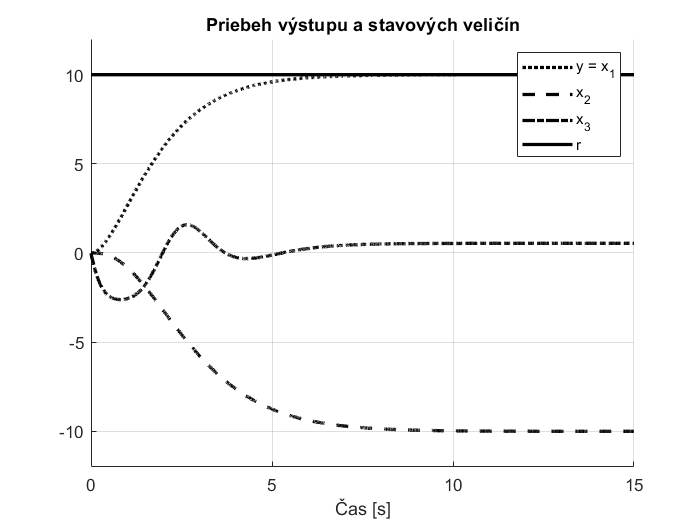


figure;
hold on;
grid on;
plot(ScopeData.time, ScopeData.signals(1).values(:,1), 'black:', 'LineWidth', 2);
plot(ScopeData.time, ScopeData.signals(1).values(:,2), 'black--', 'LineWidth', 2);
plot(ScopeData.time, ScopeData.signals(1).values(:,3), 'black-.', 'LineWidth', 2);
ylim([-12 12]);
plot(r.time, r.signals(1).values, 'black', 'LineWidth', 2);
legend("y = x_1", "x_2", "x_3", "r");
xlabel("Čas [s]");
title("Priebeh výstupu a stavových veličín");

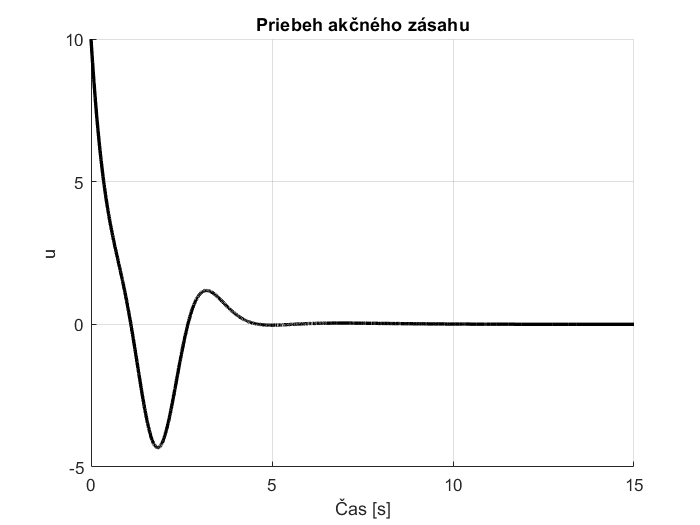

figure;
hold on;
grid on;
plot(u.time, u.signals(1).values, 'black', 'LineWidth', 2);
ylabel("u");
xlabel("Čas [s]");
title("Priebeh akčného zásahu");

Tsim = 50;
pidW = 1;
sim('svlvspr2_schema_SVLVS');

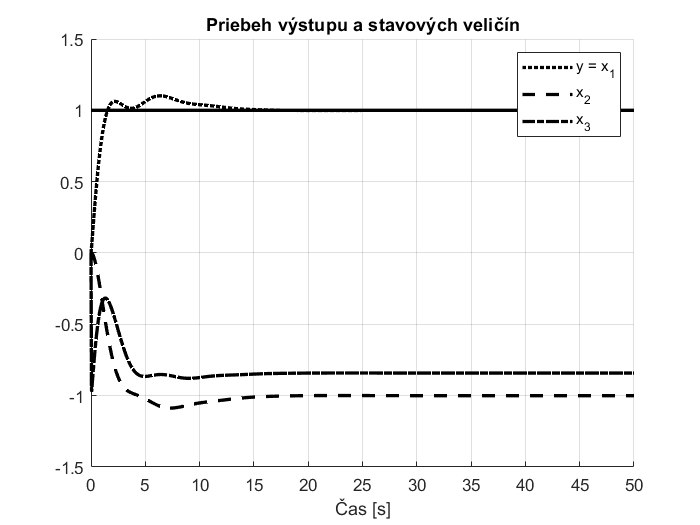

figure;
hold on;
grid on;
plot(ScopeData2.time, ScopeData2.signals(1).values(:,1), 'black:', 'LineWidth', 2);
plot(ScopeData2.time, ScopeData2.signals(1).values(:,2), 'black--', 'LineWidth', 2);
plot(ScopeData2.time, ScopeData2.signals(1).values(:,3), 'black-.', 'LineWidth', 2);
plot(ScopeData10.time, ScopeData10.signals(1).values, 'black', 'LineWidth', 2);
legend("y = x_1", "x_2", "x_3");
title("Priebeh výstupu a stavových veličín");
xlabel("Čas [s]");

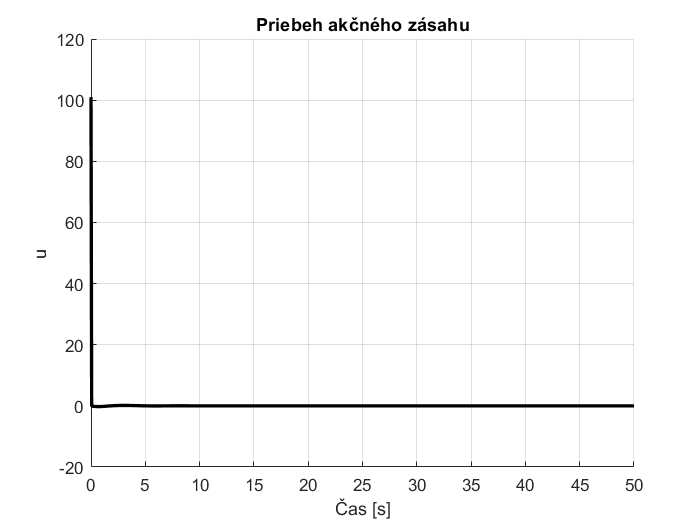

figure;
hold on;
grid on;
plot(pidu.time, pidu.Data, 'black', 'LineWidth', 2);
ylabel("u");
xlabel("Čas [s]");
title("Priebeh akčného zásahu");

Tsim = 50;
pidW = 10;
sim('svlvspr2_schema_SVLVS');

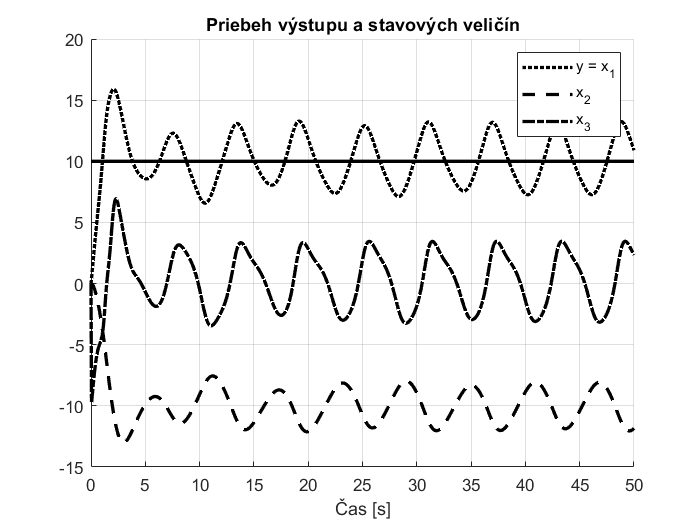

figure;
hold on;
grid on;
plot(ScopeData2.time, ScopeData2.signals(1).values(:,1), 'black:', 'LineWidth', 2);
plot(ScopeData2.time, ScopeData2.signals(1).values(:,2), 'black--', 'LineWidth', 2);
plot(ScopeData2.time, ScopeData2.signals(1).values(:,3), 'black-.', 'LineWidth', 2);
plot(ScopeData10.time, ScopeData10.signals(1).values, 'black', 'LineWidth', 2);
legend("y = x_1", "x_2", "x_3");
title("Priebeh výstupu a stavových veličín");
xlabel("Čas [s]");

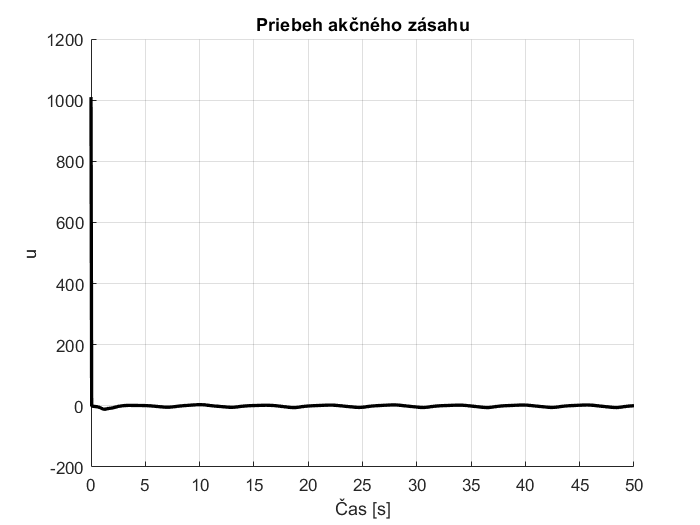

figure;
hold on;
grid on;
plot(pidu.time, pidu.Data, 'black', 'LineWidth', 2);
ylabel("u");
xlabel("Čas [s]");
title("Priebeh akčného zásahu");

Gl = tf([1 1], [1 1 1 2])


Gl =
 
        s + 1
  -----------------
  s^3 + s^2 + s + 2
 
Continuous-time transfer function.



Gr = tf([1 1 1], [1 0])


Gr =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.



A = [0 1 0; 0 0 1; -1 8 3];
B = [0;0;-6];
C = [1 0 0];
D = 0;
